Create a small world graph

h2 = WattsStrogatz(1000, 15, 0.01)

h2 =   graph with properties:

    Edges: [75000×1 table]
    Nodes: [5000×0 table]


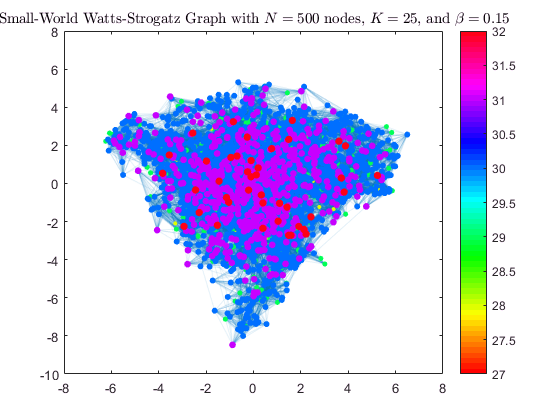

colormap hsv
deg = degree(h2);
nSizes = 2*sqrt(deg-min(deg)+0.2);
nColors = deg;
plot(h2,'MarkerSize',nSizes,'NodeCData',nColors,'EdgeAlpha',0.1)
title('Small-World Watts-Strogatz Graph with $N = 500$ nodes, $K = 25$, and $\beta = 0.15$', ...
    'Interpreter','latex')
colorbar